# MATLAB Assignment 1 - Filter/Effect

Author: Kevin Horta

## Introduction

This assigment / script is to apply the gray scale filter to a image and then erode and dilate it with image processing meathods in a MATLAB live script.

## Reading Image

Read the Image into MATLAB with the imread() function

IMG = imread('IMG1.jpg')

IMG = 183×275×3 uint8 array
IMG(:,:,1) =

   125   126   126   127   128   129   130   130   129   129   129   130   130   131   131   131   130   130   130   131   131   132   132   132   135   135   135   136   136   137   137   136   138   137   137   138   138   139   139   139   139   139   140   140   141   141   141   142   141   141   141   141   141   141   141   141   142   142   142   142   142   142   142   142   152   151   150   149   147   146   145   144   144   145   148   151   154   158   160   162   160   161   162   162   163   164   165   165   163   163   163   164   164   165   165   164   166   164   164   165   165   166   166   166   165   165   165   166   166   167   167   167   169   169   169   170   170   171   171   171   171   171   172   172   173   173   173   174   175   175   175   176   176   177   177   177   176   176   177   177   178   178   178   179   183   183   183   184   184   185   185   185   185   186   186   186   187   187   188   1

## Displaying Image

Display the Image we loading into MATLAB with imshow() function

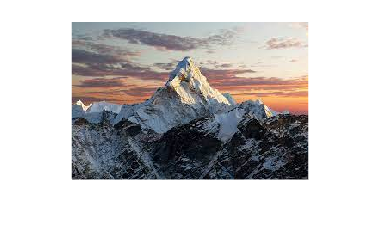

imshow(IMG)

## Applying Filter

Here we apply the gray filter to the image that converts the image pixel values from a RGB to just a single value of brightness in each pixel

IMG_G = im2gray(IMG)

IMG_G = 183×275 uint8 matrix
   139   140   140   141   142   143   144   144   143   143   143   144   144   145   145   145   143   143   143   144   144   145   145   145   148   148   148   149   149   150   150   150   152   152   152   153   153   154   154   154   154   154   155   155   156   156   156   157   156   156
   139   140   140   141   142   143   144   144   143   143   144   144   145   145   145   146   143   143   144   144   145   145   145   146   148   148   149   149   150   150   150   151   152   152   152   153   153   154   154   154   154   155   155   155   156   156   157   157   158   158
   140   140   141   142   143   144   144   145   144   144   144   144   145   145   146   146   144   144   144   145   145   146   146   146   149   149   149   149   150   150   151   151   152   152   153   153   154   154   154   155   155   155   155   156   156   157   157   157   160   160
   140   141   141   142   143   144   145   145   144   144   145  

## Applying Effect

Here we create a structuring element of a square with a size of 4x4 and then utilize it for opening the image which is erode and dilate done by MATLAB then we display it with imshow()

structure = strel("square", 4)

structure = strel is a square shaped structuring element with properties:

      Neighborhood: [4×4 logical]
    Dimensionality: 2



IMG_G_E = imopen(IMG_G,structure)

IMG_G_E = 183×275 uint8 matrix
   139   140   140   141   142   143   143   143   143   143   143   144   144   144   144   144   143   143   143   144   144   145   145   145   148   148   148   149   149   150   150   150   152   152   152   153   153   154   154   154   154   154   155   155   156   156   156   156   156   156
   139   140   140   141   142   143   143   143   143   143   144   144   145   145   145   145   143   143   144   144   145   145   145   146   148   148   149   149   150   150   150   151   152   152   152   153   153   154   154   154   154   155   155   155   156   156   157   157   158   158
   140   140   141   142   143   144   144   144   144   144   144   144   145   145   145   145   144   144   144   145   145   146   146   146   149   149   149   149   150   150   151   151   152   152   153   153   154   154   154   155   155   155   155   156   156   157   157   157   159   159
   140   141   141   142   143   144   144   144   144   144   145

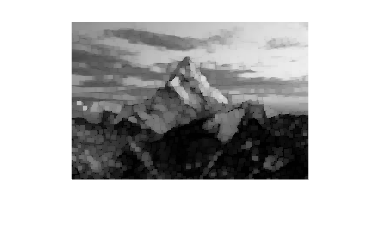


imshow(IMG_G_E)

## Saving PNG Image

Here we write the image and save it has a PNG file into our directory of the file named NEWIMAGE1

imwrite(IMG_G_E, 'NEWIMAGE1.png')